c = physconst('LightSpeed');
fc = 300e6;              % Operating frequency
lambda = c/fc;

ura = phased.URA('Size',[10 5],'ElementSpacing',[0.3 0.5]);

Nsamp = 1000;
nPower = 0.01;
rs = rng(2007);

ang1 = [40; 45];         % First signal
ang2 = [-20; 20];        % Second signal

signal = sensorsig(getElementPosition(ura)/lambda,Nsamp, ...
  [ang1 ang2],nPower);
rng(rs);                 % Restore random number generator

azelspectrum = phased.BeamscanEstimator2D('SensorArray',ura,...
       'OperatingFrequency',fc,...
       'AzimuthScanAngles',-45:45,'ElevationScanAngles',10:60,...
       'DOAOutputPort',true,'NumSignals',2);

[~,ang] = azelspectrum(signal)

ang =     40   -20
    45    20


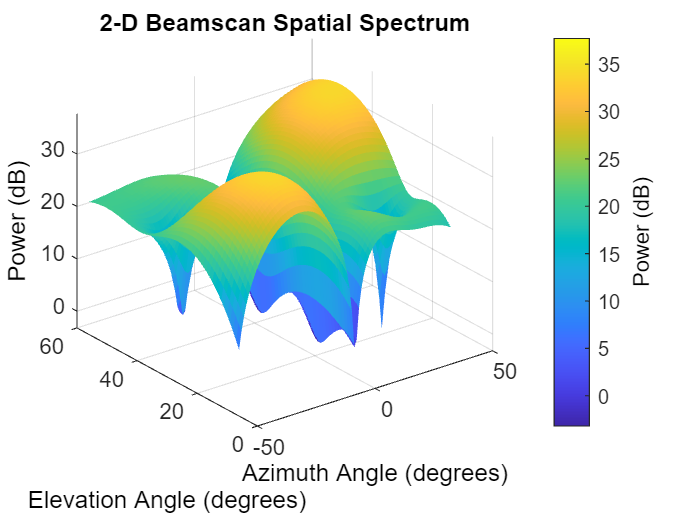



plotSpectrum(azelspectrum);